# SNW_DS_PARAM Tiny Solution Analysis

**back to **[**Fan**](https://fanwangecon.github.io)**'s **[**Intro Math for Econ**](https://fanwangecon.github.io/Math4Econ/)**,  **[**Matlab Examples**](https://fanwangecon.github.io/M4Econ/)**, or **[**Dynamic Asset**](https://fanwangecon.github.io/CodeDynaAsset/)** Repositories**

This is the example vignette for function: [**snw_ds_main**](https://github.com/FanWangEcon/PrjOptiSNW/tree/master/PrjOptiSNW/params/snw_ds_main.m) from the [**PrjOptiSNW Package**](https://fanwangecon.github.io/PrjOptiSNW/)**. **This function solves for vfi and gets distribution induced by policy functions and exogenous distributions.

## Test SNW_DS_MAIN Defaults

Call the function with testing defaults.

mp_params = snw_mp_param('default_tiny');
mp_controls = snw_mp_control('default_test');
mp_controls('bl_print_vfi') = true;
mp_controls('bl_print_ds') = true;
mp_controls('bl_print_vfi_verbose') = false;
mp_controls('bl_print_ds_verbose') = false;
mp_controls('bl_vfi_store_all') = true;
mp_controls('bl_ds_store_all') = true;
[mp_dsvfi_results] = snw_ds_main(mp_params, mp_controls);

SNW_VFI_MAIN: Finished Age Group:7 of 7
SNW_VFI_MAIN: Finished Age Group:6 of 7
SNW_VFI_MAIN: Finished Age Group:5 of 7
SNW_VFI_MAIN: Finished Age Group:4 of 7
SNW_VFI_MAIN: Finished Age Group:3 of 7
SNW_VFI_MAIN: Finished Age Group:2 of 7
SNW_VFI_MAIN: Finished Age Group:1 of 7
Elapsed time is 71.091706 seconds.
Completed SNW_VFI_MAIN;SNW_MP_PARAM=;default_tiny;SNW_MP_CONTROL=;default_test
SNW_DS_MAIN: Share of population with assets equal to upper bound on asset grid=0
SNW_DS_MAIN: Old and updated value of a2=3.664      2.5687
Elapsed time is 77.086817 seconds.
Completed SNW_DS_MAIN;SNW_MP_PARAM=;default_tiny;SNW_MP_CONTROL=;default_test
xxx tb_outcomes: all stats xxx
    OriginalVariableNames      ap_ss         c_ss          v_ss   
    _____________________    _________    __________    __________

      {'mean'        }         0.39766       0.731

## Tiny Param Results Define Frames

Define the matrix dimensions names and dimension vector values. Probability mass matrixes, Policy and Value Functions share the same ND dimensional structure.

% Grids:
age_grid = [19, 28:16:92, 100];
agrid = mp_param('agrid')';
eta_grid = mp_param('eta_grid')';
edu_grid = [0,1];
marry_grid = [0,1];
kids_grid = (1:1:mp_param('n_kidsgrid'))';
% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
cl_mp_datasetdesc = {};
cl_mp_datasetdesc{1} = containers.Map({'name', 'labval'}, {'age', age_grid});
cl_mp_datasetdesc{2} = containers.Map({'name', 'labval'}, {'savings', agrid});
cl_mp_datasetdesc{3} = containers.Map({'name', 'labval'}, {'shock', eta_grid});
cl_mp_datasetdesc{4} = containers.Map({'name', 'labval'}, {'edu', edu_grid});
cl_mp_datasetdesc{5} = containers.Map({'name', 'labval'}, {'marry', marry_grid});
cl_mp_datasetdesc{6} = containers.Map({'name', 'labval'}, {'kids', kids_grid});

## Analyze Probability Mass Along Age Dimensions

Where are the mass at? Analyze mass given state space components.

% Get the Joint distribution over all states
Phi_true = mp_dsvfi_results('Phi_true');
Phi_true = Phi_true/sum(Phi_true(:));
% Define Graph Inputs
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = false; % do not log

#### Exogenous Permanent States Mass: Life Cycle, Edu and Marraige

Tabulate value and policies along savings and shocks:

% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [2,3,6,1,5,4];
% Value Function
tb_prob_aem = ff_summ_nd_array("P(Age, EDU, MARRY))", Phi_true, true, ["sum"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  P(Age, EDU, MARRY))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    marry    edu    sum_age_19    sum_age_28    sum_age_44    sum_age_60    sum_age_76    sum_age_92    sum_age_100
    _____    _____    ___    __________    __________    __________    __________    __________    __________    ___________

      1        0       0      0.097097      0.081717      0.068773       0.05646      0.041876      0.018919     0.00052407 
      2        1       0      0.088132      0.074172      0.062424      0.051247       0.03801      0.017172     0.00047568 
      3        0       1       0.04221      0.035524      0.029897      0.024544      0.018204     0.0082

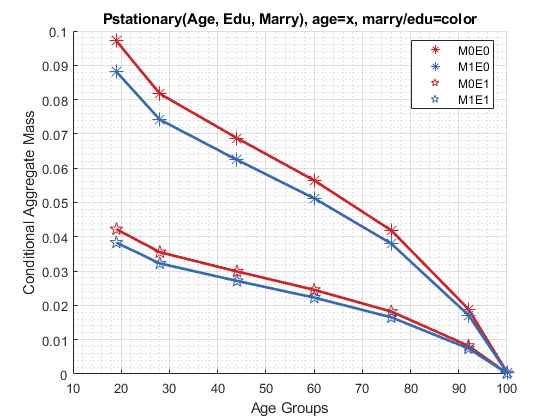

mp_support_graph('cl_st_graph_title') = {'Pstationary(Age, Edu, Marry), age=x, marry/edu=color'};
mp_support_graph('cl_st_ytitle') = {'Conditional Aggregate Mass'};
ar_row_grid = ["M0E0", "M1E0", "M0E1", "M1E1"];
mp_support_graph('cl_st_xtitle') = {'Age Groups'};
mp_support_graph('cl_scatter_shapes') = {'*', '*', 'p', 'p' };
mp_support_graph('cl_colors') = {'red', 'blue', 'red', 'blue'};
ff_graph_grid((tb_prob_aem{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

#### Kids and Marry By Age Mass

% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [2,3,4,1,6,5];
% Value Function
tb_prob_amarrykids = ff_summ_nd_array("P(Age, Kids, Marry))", Phi_true, true, ["sum"], 3, 1, cl_mp_datasetdesc, ar_permute);

xxx  P(Age, Kids, Marry))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    kids    marry    sum_age_19    sum_age_28    sum_age_44    sum_age_60    sum_age_76    sum_age_92    sum_age_100
    _____    ____    _____    __________    __________    __________    __________    __________    __________    ___________

      1       1        0        0.11481      0.094948      0.075142      0.064461       0.05301       0.025867    0.00073501 
      2       2        0       0.016183      0.020239      0.017152        0.0114      0.005348      0.0010701    1.4834e-05 
      3       3        0      0.0083148     0.0020546     0.0063766     0.0051426     0.0017225     

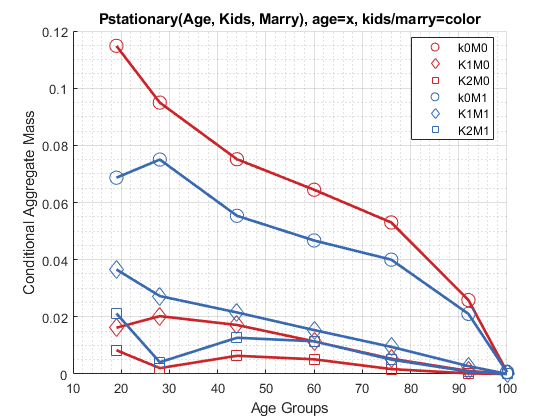

mp_support_graph('cl_st_graph_title') = {'Pstationary(Age, Kids, Marry), age=x, kids/marry=color'};
mp_support_graph('cl_st_ytitle') = {'Conditional Aggregate Mass'};
ar_row_grid = ["k0M0", "K1M0", "K2M0", "k0M1", "K1M1", "K2M1"];
mp_support_graph('cl_scatter_shapes') = { 'o', 'd' ,'s', 'o', 'd', 's'};
mp_support_graph('cl_colors') = {'red', 'red', 'red', 'blue', 'blue', 'blue'};
mp_support_graph('cl_st_xtitle') = {'Age Groups'};
ff_graph_grid((tb_prob_amarrykids{1:end, 4:end}), ar_row_grid, age_grid, mp_support_graph);

## Analyze Probability Mass Asset and Shock Dimensions

Where are the mass at?

% Get the Joint distribution over all states
Phi_true = mp_dsvfi_results('Phi_true');
Phi_true = Phi_true/sum(Phi_true(:));
% Define Graph Inputs
mp_support_graph = containers.Map('KeyType', 'char', 'ValueType', 'any');
mp_support_graph('st_legend_loc') = 'best';
mp_support_graph('bl_graph_logy') = false; % do not log

#### Asset and Shock Mass

% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [1,4,5,6,3,2];
% Value Function
tb_prob_az = ff_summ_nd_array("P(A,Z))", Phi_true, true, ["sum"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  P(A,Z))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    savings     sum_shock__1_4213    sum_shock__0_71067    sum_shock_0    sum_shock_0_71067    sum_shock_1_4213
    _____    ________    _________________    __________________    ___________    _________________    ________________

      1             0         0.042105              0.094347            0.1028          0.066749             0.016636   
      2      0.068587         0.019705               0.13585           0.16601          0.052759            0.0014544   
      3        0.5487       0.00068813              0.019614           0.10009           0.09387             0.022199   
      4        1.8519        1.791e-06            0.00018665         0.0060569          0.035405             0.017

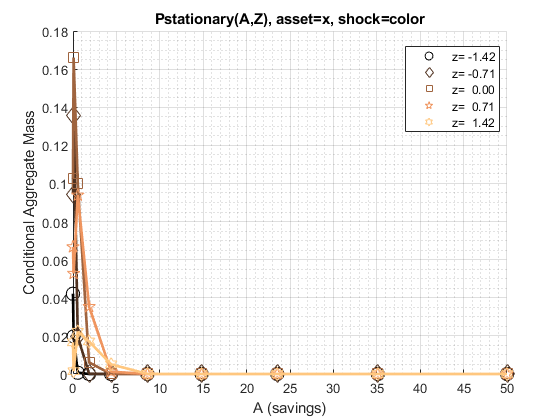

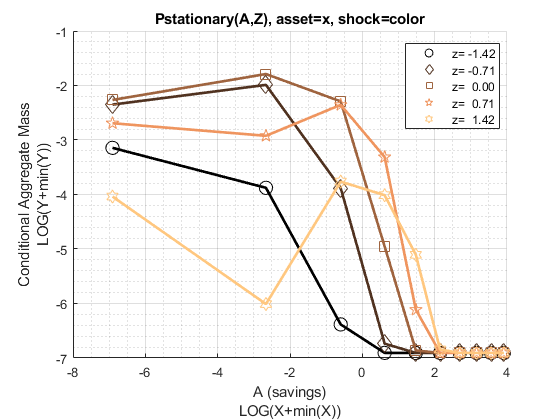

mp_support_graph('cl_st_graph_title') = {'Pstationary(A,Z), asset=x, shock=color'};
mp_support_graph('cl_st_ytitle') = {'Conditional Aggregate Mass'};
mp_support_graph('cl_st_xtitle') = {'A (savings)'};
mp_support_graph('st_rowvar_name') = 'z=';
mp_support_graph('it_legend_select') = 5; 
mp_support_graph('st_rounding') = '6.2f';
mp_support_graph('bl_graph_logy') = true;
mp_support_graph('cl_colors') = 'copper';
ff_graph_grid((tb_prob_az{1:end, 3:end})', eta_grid, agrid, mp_support_graph);% Consumption Choices

#### Asset Mass by Age

% NaN(n_jgrid,n_agrid,n_etagrid,n_educgrid,n_marriedgrid,n_kidsgrid);
ar_permute = [3,4,5,6,1,2];
% Value Function
tb_prob_aage = ff_summ_nd_array("P(A,Z))", Phi_true, true, ["sum"], 4, 1, cl_mp_datasetdesc, ar_permute);

xxx  P(A,Z))  xxxxxxxxxxxxxxxxxxxxxxxxxxx
    group    savings     sum_age_19    sum_age_28    sum_age_44    sum_age_60    sum_age_76    sum_age_92    sum_age_100
    _____    ________    __________    __________    __________    __________    __________    __________    ___________

      1             0     0.26575         0.02717      0.012933     0.0042145     0.0031499     0.0082267     0.0011905 
      2      0.068587           0         0.15825       0.11098       0.06065      0.033126      0.012712    5.4591e-05 
      3        0.5487           0        0.038239      0.055551      0.066649      0.052131      0.023699    0.00018928 
      4        1.8519           0      4.1234e

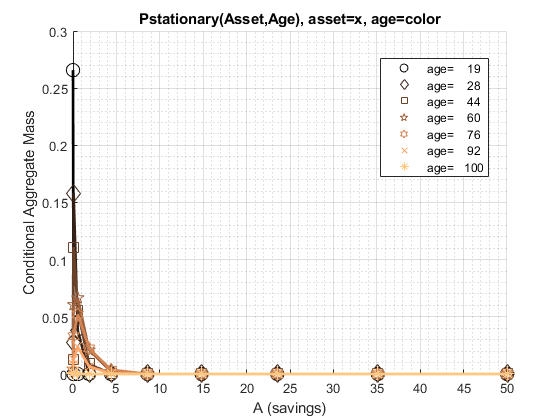

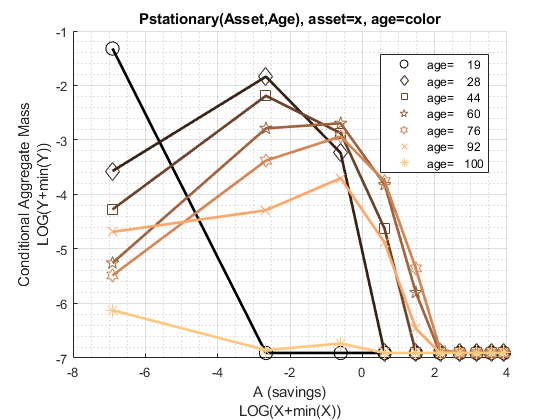

mp_support_graph('cl_st_graph_title') = {'Pstationary(Asset,Age), asset=x, age=color'};
mp_support_graph('cl_st_ytitle') = {'Conditional Aggregate Mass'};
mp_support_graph('cl_st_xtitle') = {'A (savings)'};
mp_support_graph('st_rowvar_name') = 'age=';
mp_support_graph('it_legend_select') = 5; 
mp_support_graph('st_rounding') = '6.0f';
mp_support_graph('bl_graph_logy') = true;
mp_support_graph('cl_colors') = 'copper';
ff_graph_grid((tb_prob_aage{1:end, 3:end})', age_grid, agrid, mp_support_graph);% Consumption Choices

## Probability Statistics A, C and V Conditional on Ages

Where are the mass at?

Phi_true = mp_dsvfi_results('Phi_true');
ap_ss = mp_dsvfi_results('ap_ss');
c_ss = mp_dsvfi_results('c_ss');
v_ss = mp_dsvfi_results('v_ss');
for it_ctr=1:size(ap_ss, 1)
    display(['age =' num2str(age_grid(it_ctr))]);
    % construct input data
    Phi_true_age = Phi_true(it_ctr, :, :, : ,: ,:);
    ap_ss_age = ap_ss(it_ctr, :, :, : ,: ,:);
    c_ss_age = c_ss(it_ctr, :, :, : ,: ,:);
    v_ss_age = v_ss(it_ctr, :, :, : ,: ,:);   
    mp_cl_ar_xyz_of_s = containers.Map('KeyType','char', 'ValueType','any');
    mp_cl_ar_xyz_of_s('ap_ss') = {ap_ss_age(:), zeros(1)};
    mp_cl_ar_xyz_of_s('c_ss') = {c_ss_age(:), zeros(1)};
    mp_cl_ar_xyz_of_s('v_ss') = {v_ss_age(:), zeros(1)};
    mp_cl_ar_xyz_of_s('ar_st_y_name') = ["ap_ss", "c_ss", "v_ss"];
    
    % controls
    mp_support = containers.Map('KeyType','char', 'ValueType','any');
    mp_support('ar_fl_percentiles') = [0.01 10 25 50 75 90 99.99];
    mp_support('bl_display_final') = true;
    mp_support('bl_display_detail') = false;    
    mp_support('bl_display_drvm2outcomes') = false;  
    mp_support('bl_display_drvstats') = false;
    mp_support('bl_display_drvm2covcor') = false;

    % Call Function     
    mp_cl_mt_xyz_of_s = ff_simu_stats(Phi_true_age(:)/sum(Phi_true_age,'all'), mp_cl_ar_xyz_of_s, mp_support);
end+

age =19


xxx tb_outcomes: all stats xxx
    OriginalVariableNames     ap_ss        c_ss         v_ss   
    _____________________    ________    _________    _________

      {'mean'        }        0.14234      0.50175       -8.272
      {'sd'          }        0.13301       0.3087       7.2438
      {'coefofvar'   }        0.93447      0.61526      -0.8757
      {'min'         }              0     0.095434      -42.186
      {'max'         }             50        34.73       4.6012
      {'pYis0'       }       0.019346            0            0
      {'pYls0'       }              0            0      0.94228
      {'pYgr0'       }        0.98065            1     0.057716
      {'pYisMINY'    }       0.019346      0.01731    0.0019545
      {'pYisMAXY'    }              0            0            0
      {'p0_01'       }              0     0.095434      -42.186


age =28


xxx tb_outcomes: all stats xxx
    OriginalVariableNames     ap_ss        c_ss          v_ss   
    _____________________    ________    _________    __________

      {'mean'        }        0.28858      0.60987        -5.942
      {'sd'          }        0.30253      0.38607        5.6237
      {'coefofvar'   }         1.0484      0.63303      -0.94643
      {'min'         }              0      0.11117       -39.417
      {'max'         }             50       34.778        3.8351
      {'pYis0'       }       0.032693            0             0
      {'pYls0'       }              0            0        0.8648
      {'pYgr0'       }        0.96731            1        0.1352
      {'pYisMINY'    }       0.032693     0.018415    0.00035862
      {'pYisMAXY'    }              0            0             0
      {'p0_01'       }              0      0.11117  

age =44


xxx tb_outcomes: all stats xxx
    OriginalVariableNames     ap_ss        c_ss        v_ss   
    _____________________    ________    ________    _________

      {'mean'        }        0.57274     0.74877      -4.2554
      {'sd'          }        0.61056     0.52349       4.3245
      {'coefofvar'   }          1.066     0.69914      -1.0162
      {'min'         }              0     0.13715      -27.758
      {'max'         }             50      35.639        3.023
      {'pYis0'       }       0.019455           0            0
      {'pYls0'       }              0           0      0.82931
      {'pYgr0'       }        0.98055           1      0.17069
      {'pYisMINY'    }       0.019455    0.017891    0.0012043
      {'pYisMAXY'    }              0           0            0
      {'p0_01'       }              0     0.13715      -27.758
      {'p10' 

age =60


xxx tb_outcomes: all stats xxx
    OriginalVariableNames     ap_ss        c_ss         v_ss   
    _____________________    ________    _________    _________

      {'mean'        }        0.77929       1.0084       -2.923
      {'sd'          }        0.84119      0.82285       3.2688
      {'coefofvar'   }         1.0794      0.81599      -1.1183
      {'min'         }              0      0.13467      -19.236
      {'max'         }          49.06        41.09       2.2186
      {'pYis0'       }        0.02304            0            0
      {'pYls0'       }              0            0      0.82667
      {'pYgr0'       }        0.97696            1      0.17333
      {'pYisMINY'    }        0.02304     0.017197    0.0011279
      {'pYisMAXY'    }              0            0            0
      {'p0_01'       }              0      0.13467      -19.236


age =76


xxx tb_outcomes: all stats xxx
    OriginalVariableNames      ap_ss        c_ss          v_ss   
    _____________________    _________    _________    __________

      {'mean'        }         0.55122      0.95643       -2.1332
      {'sd'          }         0.58244      0.97169        2.3975
      {'coefofvar'   }          1.0566        1.016       -1.1239
      {'min'         }               0      0.20333       -12.867
      {'max'         }          35.117       52.696        1.4924
      {'pYis0'       }        0.031899            0             0
      {'pYls0'       }               0            0       0.78036
      {'pYgr0'       }          0.9681            1       0.21964
      {'pYisMINY'    }        0.031899     0.020561    1.7118e-11
      {'pYisMAXY'    }               0            0             0
      {'p0_01'       }               0  

age =92


xxx tb_outcomes: all stats xxx
    OriginalVariableNames      ap_ss        c_ss        v_ss   
    _____________________    _________    ________    _________

      {'mean'        }        0.075018      1.0552      -1.4812
      {'sd'          }         0.18222     0.99621        1.944
      {'coefofvar'   }          2.4291     0.94408      -1.3124
      {'min'         }               0     0.20333       -9.076
      {'max'         }          8.5734      74.078       1.0155
      {'pYis0'       }         0.57901           0            0
      {'pYls0'       }               0           0      0.79825
      {'pYgr0'       }         0.42099           1      0.20175
      {'pYisMINY'    }         0.57901     0.11851    0.0021605
      {'pYisMAXY'    }               0           0            0
      {'p0_01'       }               0     0.20333       -9.076


age =100


xxx tb_outcomes: all stats xxx
    OriginalVariableNames    ap_ss      c_ss        v_ss   
    _____________________    _____    ________    _________

      {'mean'        }          0      0.33969      -4.0035
      {'sd'          }          0      0.31001       1.9039
      {'coefofvar'   }        NaN      0.91263     -0.47557
      {'min'         }          0      0.20333      -8.8362
      {'max'         }          0       82.651       0.9879
      {'pYis0'       }          1            0            0
      {'pYls0'       }          0            0      0.94323
      {'pYgr0'       }          0            1     0.056773
      {'pYisMINY'    }          1      0.58339    0.0045607
      {'pYisMAXY'    }          1            0            0
      {'p0_01'       }          0      0.20333      -8.8362
      {'p10'         }          0      0.20333      